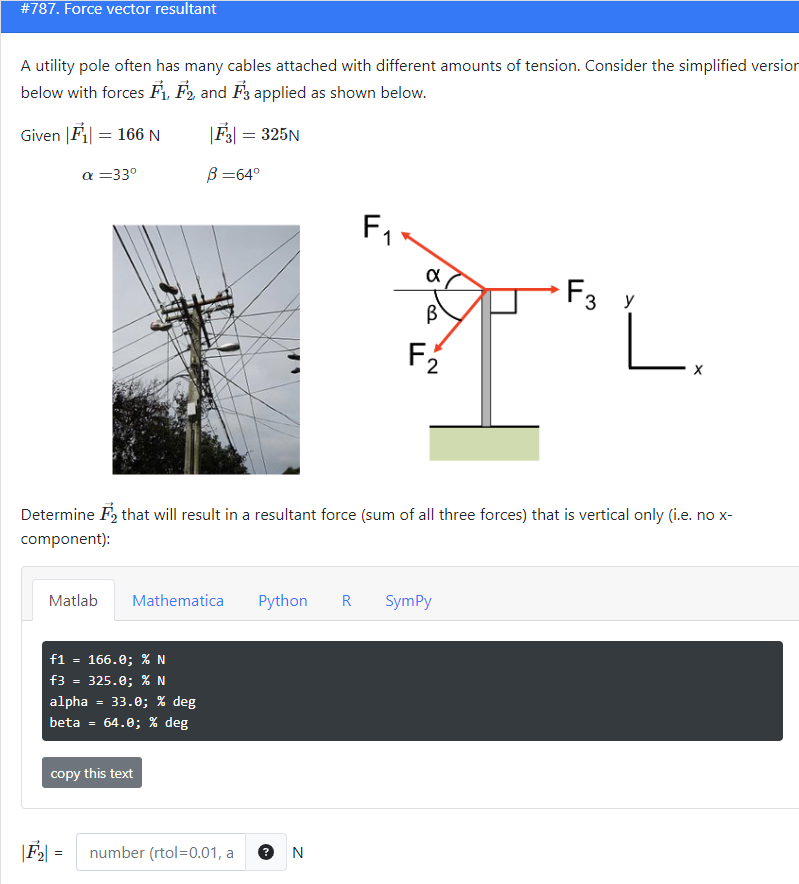

% #787. Force vector resultant

f1 = 166.0; % N
f3 = 325.0; % N
alpha = 33.0; % deg
beta = 64.0; % deg

syms f2

ff1 = f1*[-cosd(alpha),sind(alpha)];
ff3 = [f3,0];
eqn1 = ff1(1) + ff3(1) + f2*-cosd(beta) == 0;
[f2] = vpasolve(eqn1,[f2]);
f2

$$f2 = 423.7977044836121170013398978255$$

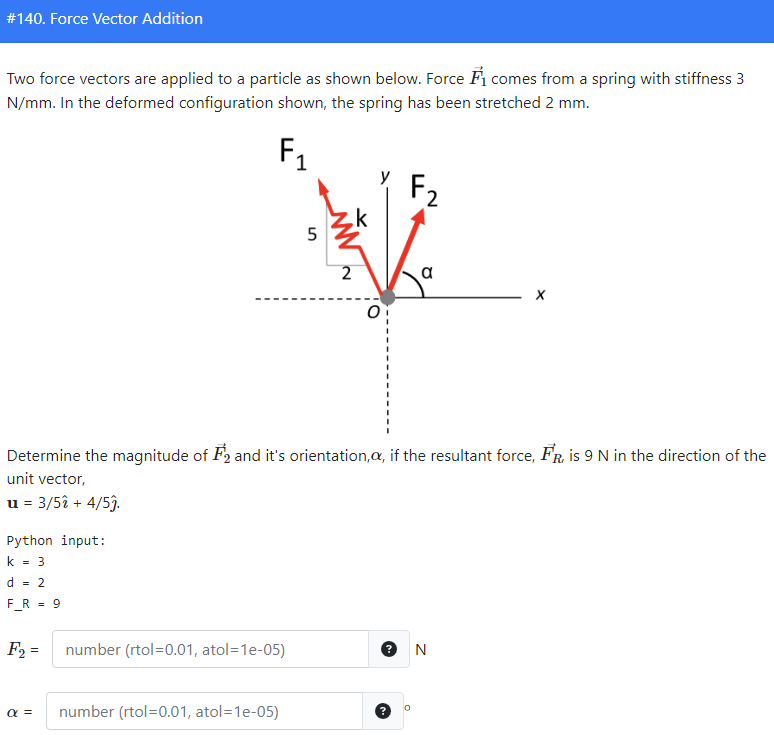

%% #140. Force Vector Addition


k = 3;
d = 2;
F_R = 9;

syms alpha f2
unitf1 = [-2,5];
unitf1 = unitf1/norm(unitf1);

ff1 = unitf1*k*d;

ff2 = f2*[cosd(alpha),sind(alpha)];

eqn1 = ff1 + ff2 == F_R*[3/5,4/5];
[f2,alpha] = vpasolve(eqn1,[f2,alpha])

$$f2 = 7.8003672820745765563600155261346$$

$$alpha = 12.055216795303219385211624105433$$

ans = -1.6499

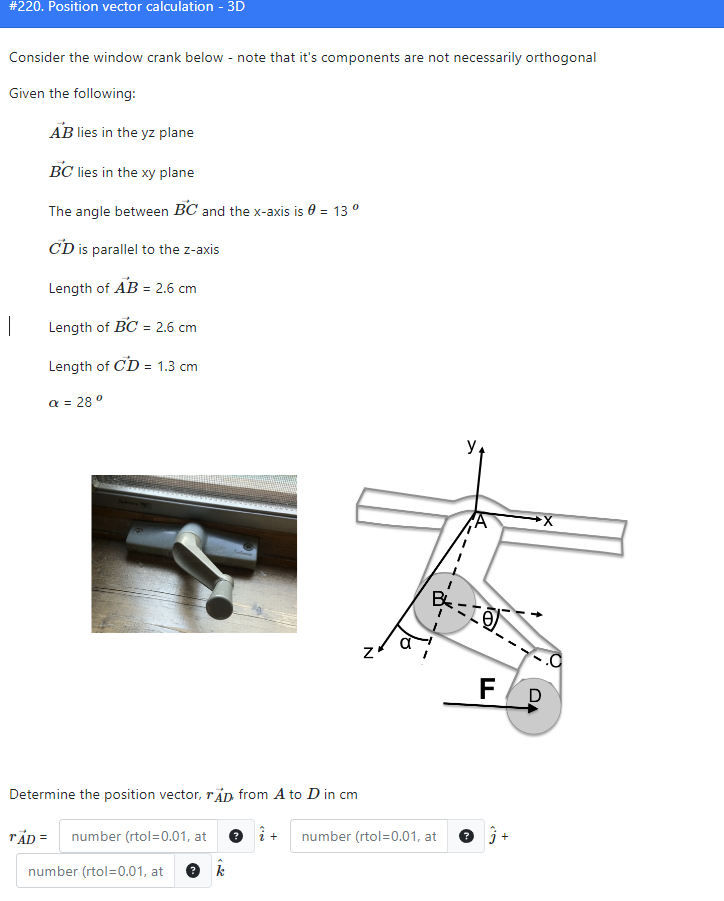

% #220. Position vector calculation - 3D
theta = 13;
ab = 2.6;
bc = 2.6;
cd = 1.3;
alpha = 28;

ab = ab*[0,-sind(alpha),cosd(alpha)];
bc = bc*[cosd(theta),-sind(theta),0];
cd = cd*[0,0,1];

ad = ab + bc + cd

ad =     2.5334   -1.8055    3.5957


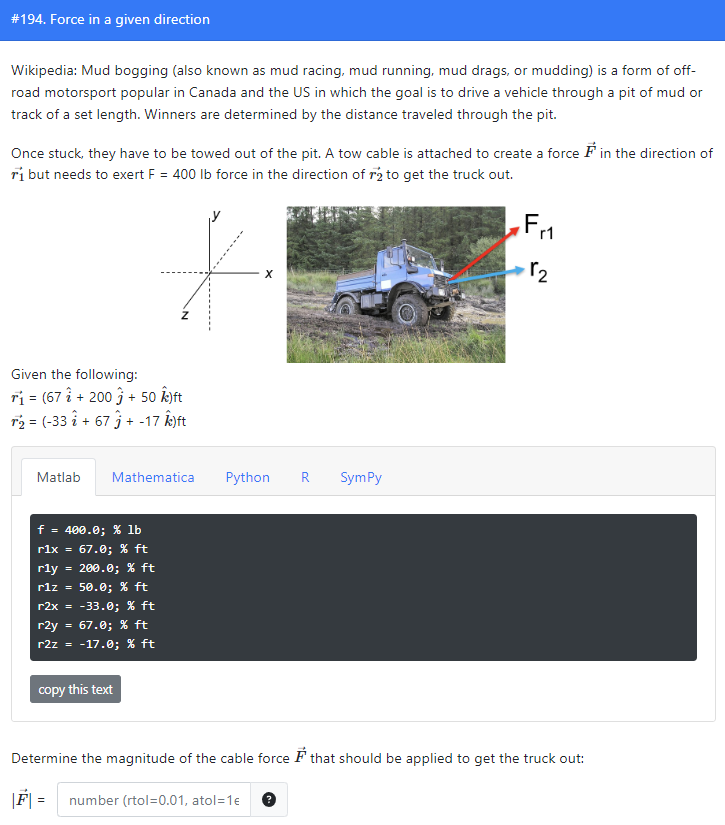

% #194. Force in a given direction
% the projection on r2 should be f
f = 400.0; % lb
r1x = 67.0; % ft
r1y = 200.0; % ft
r1z = 50.0; % ft
r2x = -33.0; % ft
r2y = 67.0; % ft
r2z = -17.0; % ft

r1 = [r1x,r1y,r1z];
r1 = r1/norm(r1);
r2 = [r2x,r2y,r2z];

syms fr;
fr1 = fr*r1

$$fr1 = \left(\begin{array}{ccc} \frac{67\,\sqrt{5221}\,\mathrm{fr}}{15663} & \frac{200\,\sqrt{5221}\,\mathrm{fr}}{15663} & \frac{50\,\sqrt{5221}\,\mathrm{fr}}{15663} \end{array}\right)$$

eqn1 = dot(fr1,r2)/norm(r2) ==f;
fr = vpasolve(eqn1,fr)

$$fr = 642.37347760209644163167654491351$$

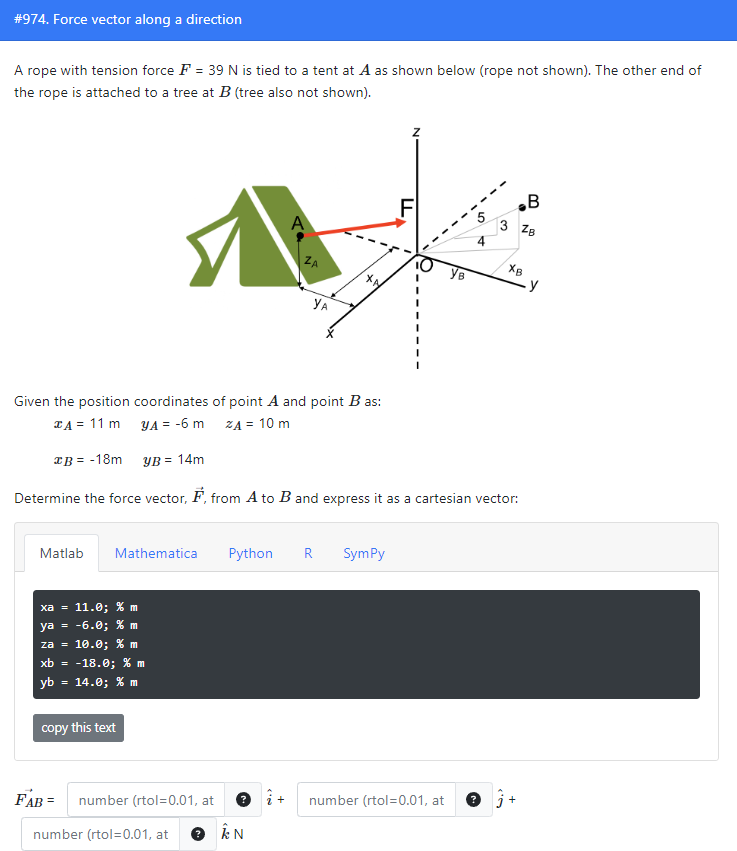

% #974. Force vector along a direction
xa = 11.0; % m
ya = -6.0; % m
za = 10.0; % m
xb = -18.0; % m
yb = 14.0; % m
f = 39;

db = norm([xb,yb]);
zb = db/4*3;

aa = [xa,ya,za];
bb = [xb,yb,zb];

rab = (bb-aa);
uab = rab/norm(rab);
fab = uab*f

fab =   -31.4720   21.7048    7.7081


p = 29

theta = 42

l = 1.5800

r =    -1.0572    2.7542         0


p =    21.5512   19.4048         0


ans =          0         0  -79.8709


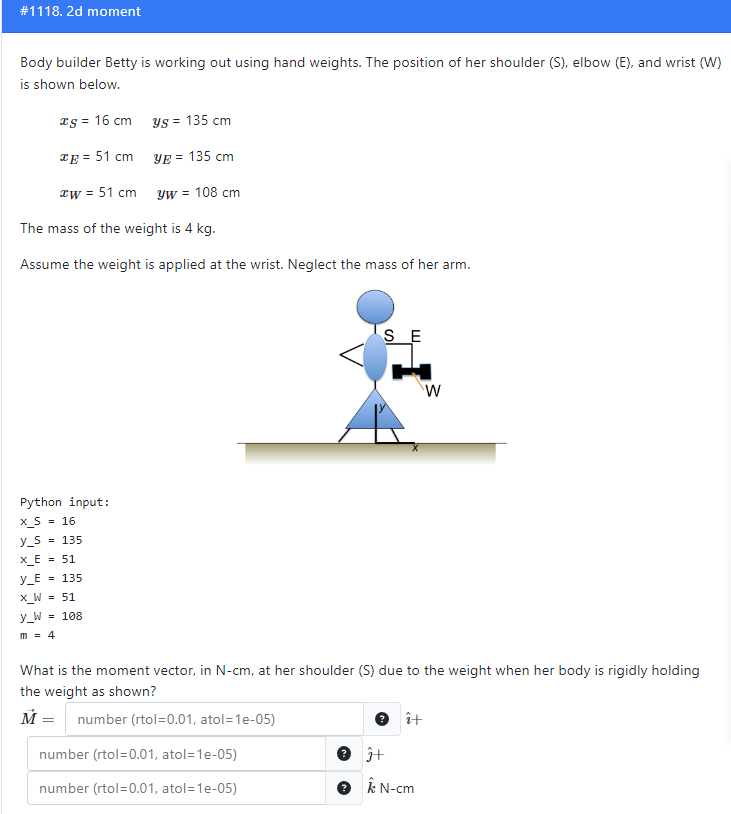

% #1118. 2d moment
x_S = 16;  
y_S = 135;  
x_E = 51; 
y_E = 135; 
x_W = 51; 
y_W = 108;
m = 4 ;

r_sw = [x_W-x_S,y_W-y_S,0];
fw = [0,-m*9.81,0];
M = vpa(cross(r_sw,fw))

$$M = \left(\begin{array}{ccc} 0 & 0 & -1373.4 \end{array}\right)$$

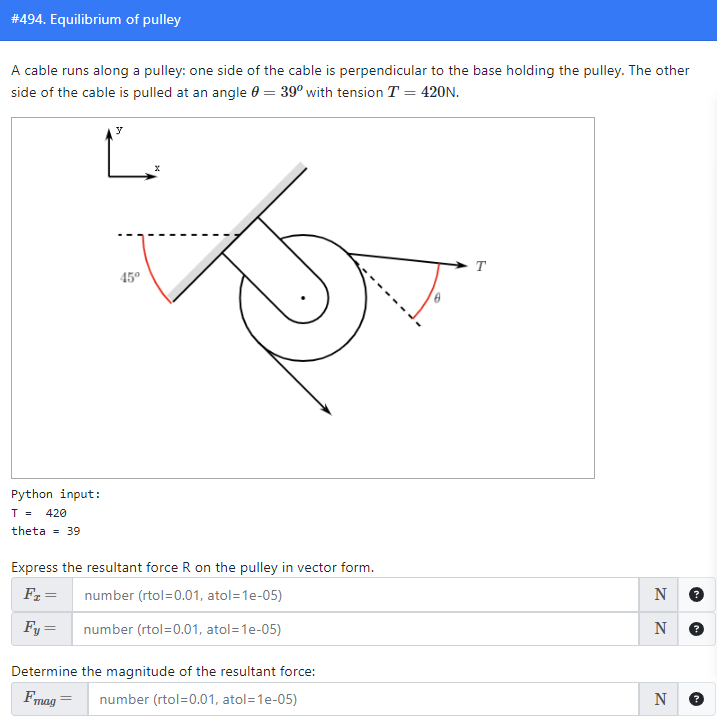

% #494. Equilibrium of pulley
T = 420;
theta = 39;
alpha = 45;
t1 = T*[sind(alpha),-cosd(alpha),0];
t2 = T*[sind(theta + alpha),-cosd(theta + alpha),0];
fr = t1+t2

fr =   714.6840  340.8868         0


m_fr = norm(fr)

m_fr = 791.8189

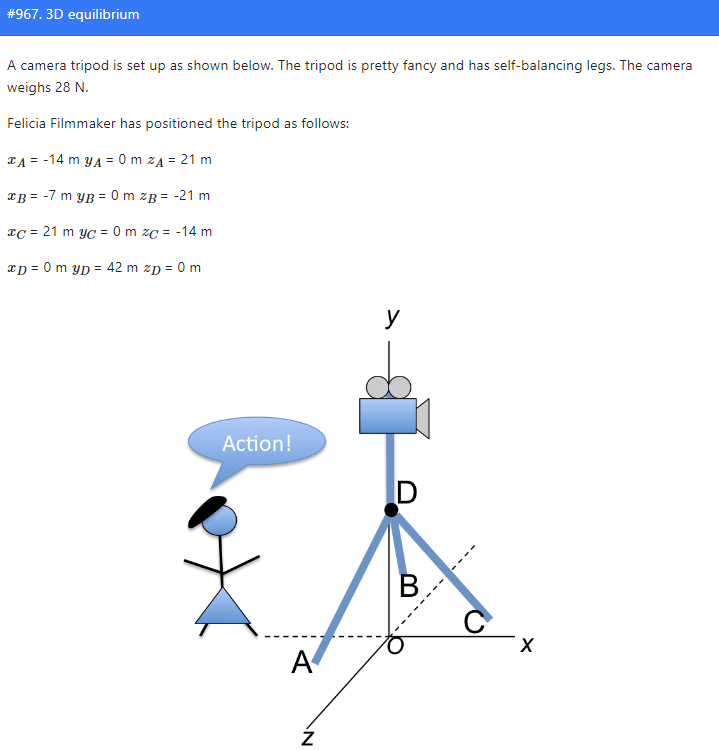

% #967. 3D equilibrium
% The sum of three forces are equal to w
x_A = -14;  
y_A = 0; 
z_A = 21; 
x_B = -7; 
y_B = 0; 
z_B = -21; 
x_C = 21; 
y_C = 0;
z_C = -14 ;
x_D = 0 ;
y_D = 42 ;
z_D = 0;
w = 28;

fw = [0,-w,0];
ad = [x_D-x_A,y_D-y_A,z_D-z_A];
bd = [x_D-x_B,y_D-y_B,z_D-z_B];
cd = [x_D-x_C,y_D-y_C,z_D-z_C];
unit_ad = ad/norm(ad);
unit_bd = bd/norm(bd);
unit_cd = cd/norm(cd);

syms fa fb fc;
eqn1 = unit_ad*fa + unit_bd*fb + unit_cd*fc + fw ==[0,0,0];
[fa,fb,fc] = vpasolve(eqn1,[fa,fb,fc])

$$fa = 14.373333333333333333333333333333$$

$$fb = 6.3301746509169169297935859048509$$

$$fc = 11.76$$

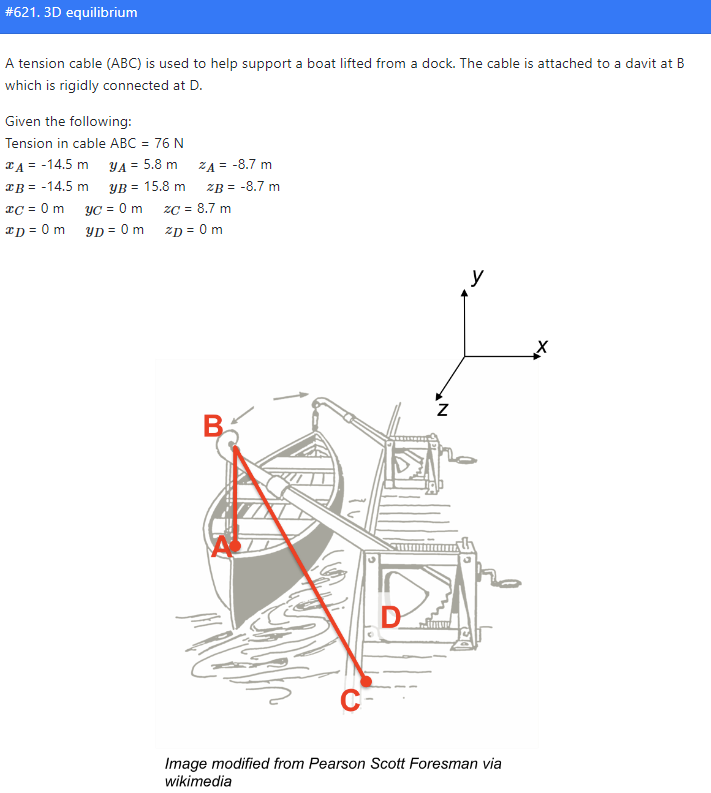

% #621. 3D equilibrium
x_A = -14.5; % m
y_A = 5.8; % m
z_A = -8.7; % m
x_B = -14.5; % m
y_B = 15.8; % m
z_B = -8.7; % m
x_C = 0.0; % m
y_C = 0.0; % m
z_C = 8.7; % m
x_D = 0.0; % m
y_D = 0.0; % m
z_D = 0.0; % m
t = 76;
rdb = [x_B-x_D,y_B-y_D,z_B-z_D];
ba = [x_A-x_B,y_A-y_B,z_A-z_B];
bc = [x_C-x_B,y_C-y_B,z_C-z_B];
ba = ba/norm(ba);
bc = bc/norm(bc);

fr = t*ba + t*bc;
M = vpa(cross(rdb,fr))

$$M = \left(\begin{array}{ccc} -282.90788024064613637165166437626 & 347.16681876649550986257963813841 & 1102.0 \end{array}\right)$$

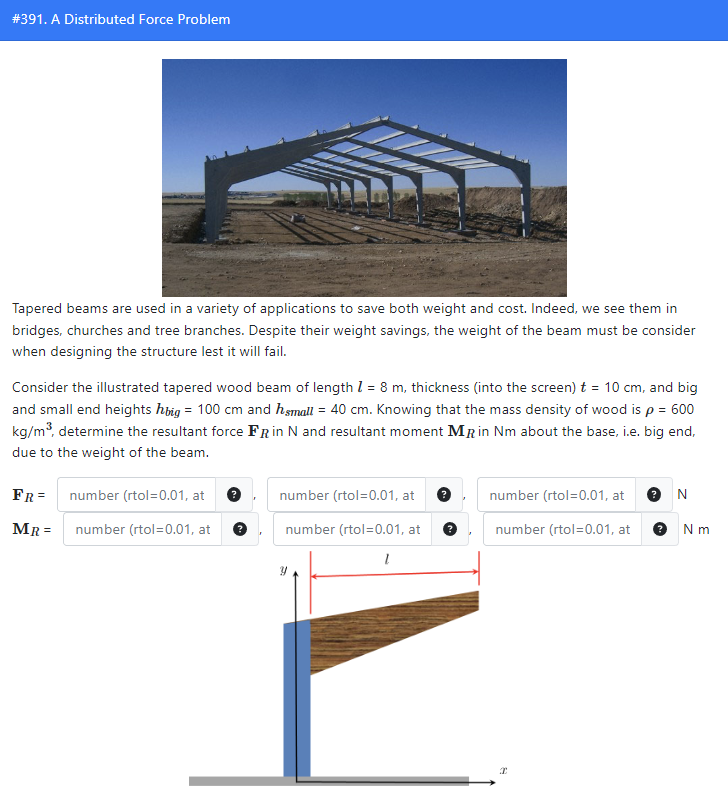

% #391. A Distributed Force Problem
l = 8;
h_b = 0.8;
h_s = 0.4;
ro  = 800;
t = 0.1;
syms x y h_x
% First find lost length of tri
eqn1 = h_s/h_b == y/(y+l);
y = solve(eqn1,y);

$$y = 8$$

% Find h_x
l_total = l+y;
% eqn2 = h_s/h_b == (l_total-x)/(l_total);
h_x = (l_total-x)/l_total*h_b;
% Find dA * ro * g *t

fn = ro*9.81*h_x*t; 

FR = vpa(int(fn,x,0,l));
MR = vpa(int(fn*x,x,0,l));
% Direction of moment should be out of the screen 
FR = [0,-FR,0]

$$FR = \left(\begin{array}{ccc} 0 & -3767.04 & 0 \end{array}\right)$$

MR = [0,0,-MR]

$$MR = \left(\begin{array}{ccc} 0 & 0 & -13393.92 \end{array}\right)$$

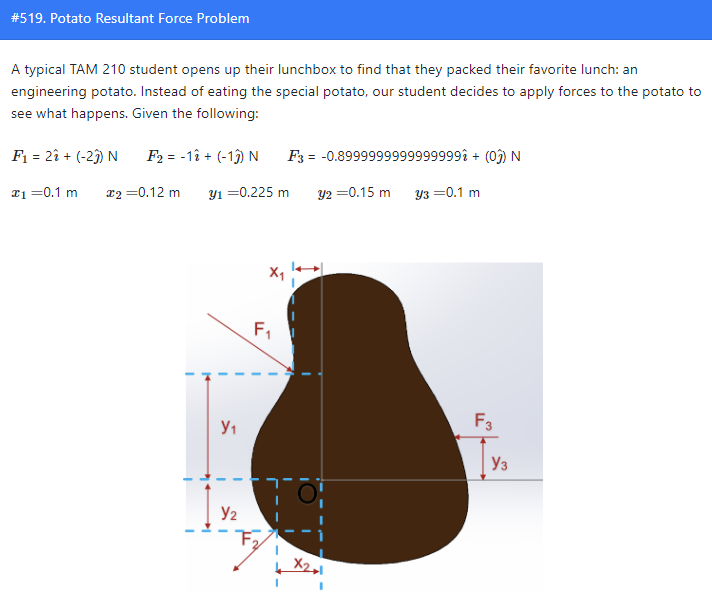

% #519. Potato Resultant Force Problem
F1x = 2;
F1y = -2;
F2x = -1;
F2y = -1;
F3x = -0.8999999999999999;
F3y = 0;
x1 = 0.1;
y1 = 0.225;
x2 = 0.12;
y2 = 0.15;
y3 = 0.1;

F1 = [F1x,F1y,0];
F2 = [F2x,F2y,0];
F3 = [F3x,F3y,0];
FR = F1 + F2 + F3;
m_FR = norm(FR)

m_FR = 3.0017


r1 = [-x1,y1,0];
r2 = [-x2,-y2,0];
r3 = [0,y3,0];

M = cross(r1,F1) + cross(r2,F2) + cross(r3,F3)

M =          0         0   -0.1900


M = vpa(abs(M))

$$M = \left(\begin{array}{ccc} 0 & 0 & 0.19 \end{array}\right)$$

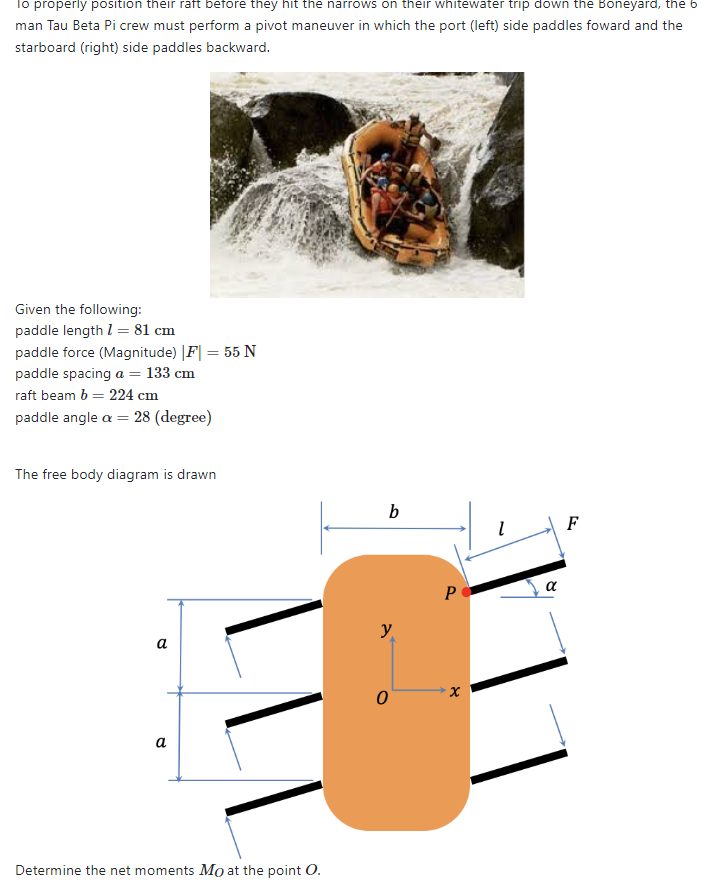

% #315. Force Couple
% For this question, calculating P and O are the same
l = 81/100;
f = 55;
b = 224/100;
a = 133/100;
alpha = 28;

f = f*[sind(alpha),-cosd(alpha),0];
r1 = [b/2+l*cosd(alpha),a+l*sind(alpha),0];
r2 = [b/2+l*cosd(alpha),l*sind(alpha),0];
r3 = [b/2+l*cosd(alpha),-a+l*sind(alpha),0];
M = cross(r1,f) + cross(r2,f) + cross(r3,f);
M = vpa(2*M)

$$M = \left(\begin{array}{ccc} 0 & 0 & -593.63743032065951865661190822721 \end{array}\right)$$

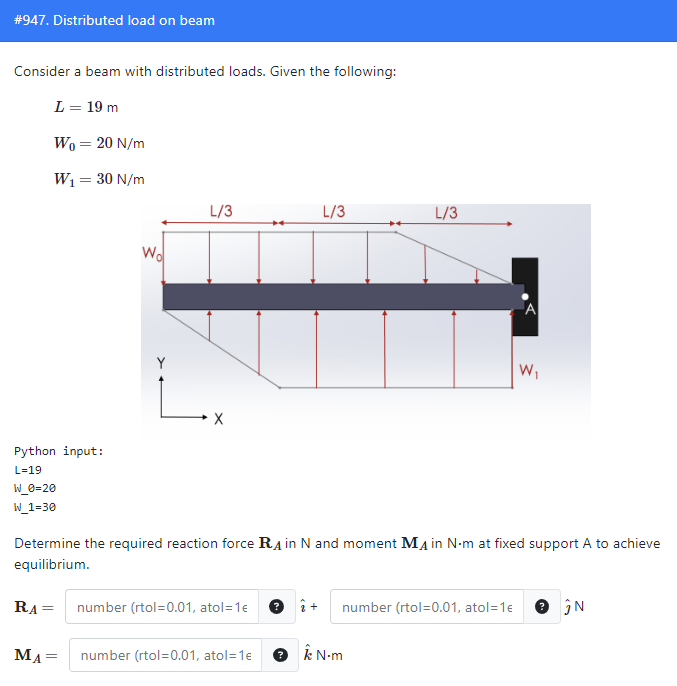

% #947. Distributed load on beam
% View A as origin
L=19;
W_0=20;
W_1=30;

syms x;
fn1 = -3*W_0/L*x

$$fn1 = -\frac{60\,x}{19}$$

F0 = int(W_0,x,-L,-L/3) + int(fn1,x,-L/3,0)

$$F0 = \frac{950}{3}$$

M0 = int(x*W_0,x,-L,-L/3) + int(x*fn1,x,-L/3,0)

$$M0 = -\frac{93860}{27}$$


fn2 = -3*W_1/L*(x+L)

$$fn2 = -\frac{90\,x}{19}-90$$

F1 = int(-W_1,x,-2*L/3,0) + int(fn2,x,-L,-2*L/3)

$$F1 = -475$$

M1 = int(x*-W_1,x,-2*L/3,0) + int(x*fn2,x,-L,-2*L/3)

$$M1 = \frac{34295}{9}$$

% Remember the direction 
% Counterclockwise is neg for Moment
FR = -vpa(-(F0+F1))

$$FR = -158.33333333333333333333333333333$$

MR = vpa(M0 + M1)

$$MR = 334.25925925925925925925925925926$$

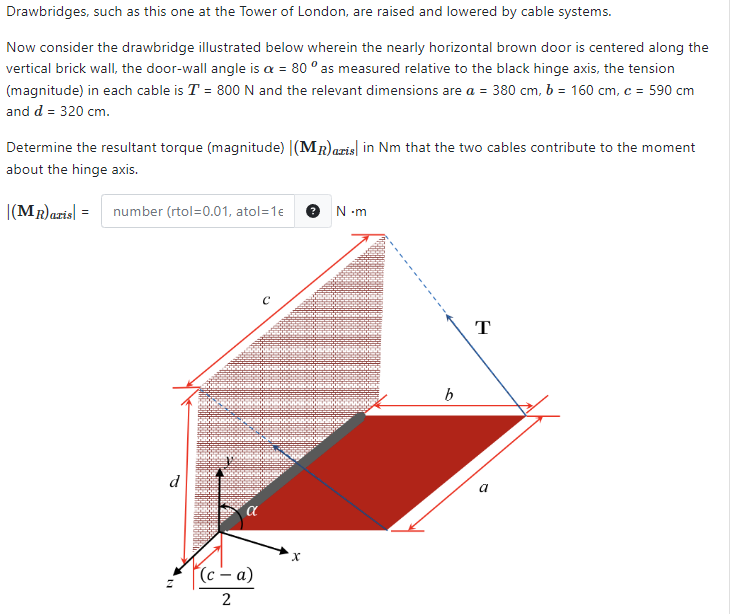

% #854. A 3D Resultant Problem

% 注意单位
alpha = 85;
t = 700;
a = 350/100;
b = 170/100;
c = 530/100;
d = 390/100;

p1 = [0,d,(c-a)/2];
p2 = [b*sind(alpha),b*cosd(alpha),0];

ft = t*(p1-p2)/norm(p1-p2);
m = 2*cross(p1,ft)

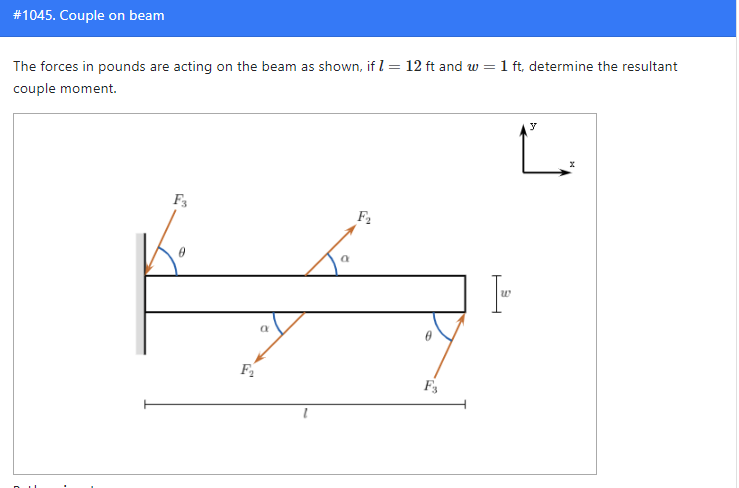

% #1045. Couple on beam
l = 14;
w = 2;
f1 = 97; 
f2 = 148;
f3 = 129;
theta = 90;
alpha = 20;

r1 = [l/2,w/2,0];
r2 = [0,w/2,0];
r3 = [-l/2,w/2,0];

f1 = f1*[1,0,0];
f2 = f2*[cosd(alpha),sind(alpha),0];
f3 = f3*[-cosd(theta),-sind(theta),0];
M = cross(r1,f1) + cross(r2,f2) + cross(r3,f3);
M = 2*vpa(M)

$$M = \left(\begin{array}{ccc} 0 & 0 & 1333.8509842473711159982485696673 \end{array}\right)$$

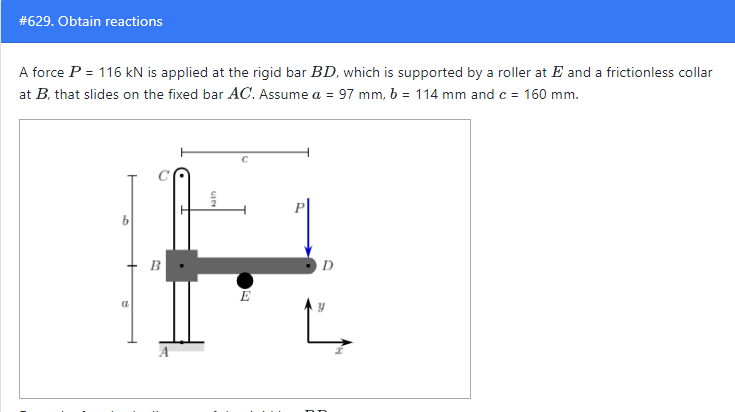

% #629. Obtain reactions
% Determine the support reactions at the collar B
% Frictionless collar means no vertical forces on B
a = 97.0; % mm
b = 114.0; % mm
c = 160.0; % mm
P = 116.0; % kN

FB = [0,0,0]

FB =      0     0     0


M = P*c/2

M = 9280

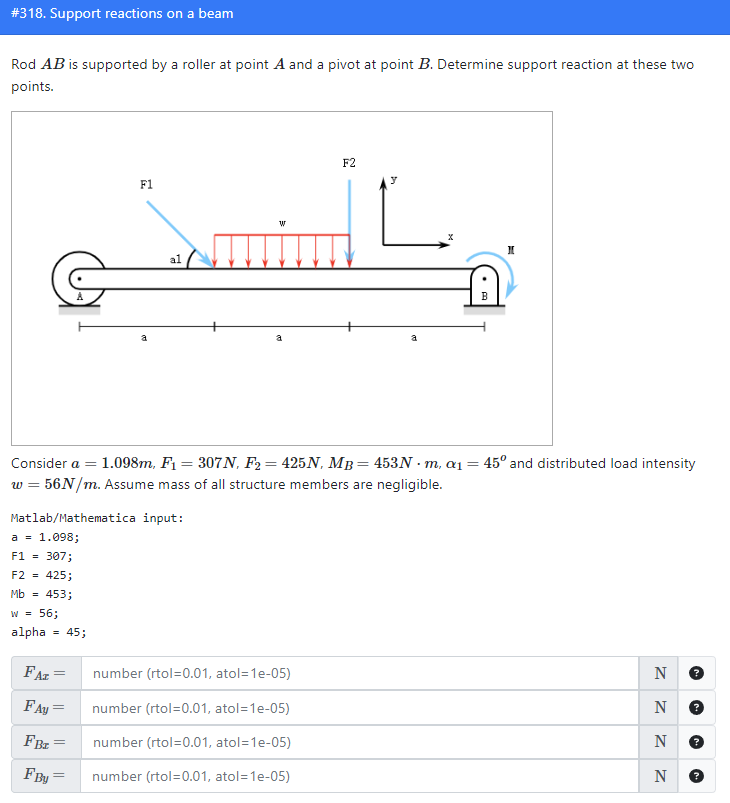

% #318. Support reactions on a beam
a = 0.880;
F1 = 492;
F2 = 409;
Mb = 314;
w = 54;
alpha = 45;

syms fay fbx fby

F1 = F1 * [cosd(alpha),-sind(alpha),0];
F2 = [0,-F2,0];
Fw = [0,-w*a,0];
FA = [0,fay,0];
FB = [fbx,fby,0];

eqn1 = F1 + F2 + Fw + FA + FB == [0,0,0]

$$eqn1 = \left(\begin{array}{ccc} \mathrm{fbx}+\frac{6120260591567735}{17592186044416}=0 & \mathrm{fay}+\mathrm{fby}-\frac{884465335285283}{1099511627776}=0 & 0=0 \end{array}\right)$$


r3a = [-3*a,0,0];
r2a = [-2*a,0,0];
r1a = [-1*a,0,0];
raa = [-1.5*a,0,0];

eqn2 = Mb + fay*3*a + F2(2)*a + Fw(2)*1.5*a + F1(2)*2*a == 0 

$$eqn2 = \frac{66\,\mathrm{fay}}{25}-\frac{3963433225942266407}{5497558138880000}=0$$

% eqn3 = cross(-r1a,F1) + cross(-r2a,F2) + cross(-r3a,FB) + cross(-raa,Fw) == 0
[fay,fbx,fby] = vpasolve(eqn1,eqn2,[fay,fbx,fby])

$$fay = 273.08496362312700670593061879503$$

$$fbx = -347.89653634378140623084618709981$$

$$fby = 531.33157272065443817844039365423$$

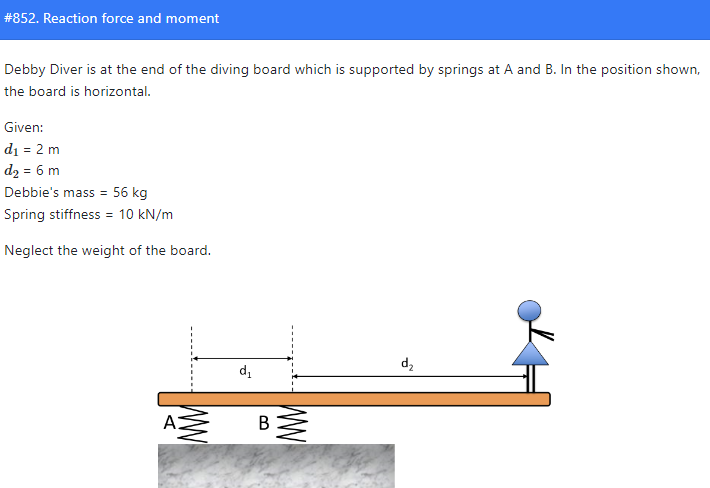

% #852. Reaction force and moment

d1 = 3.0; % m
d2 = 9.0; % m
m = 46.0; % kg
k = 19.0; % kN/m

syms fay fby;

eqn1 = fay + fby + -m*9.81 == 0;
eqn2 = m*9.81 *(d1+d2) == fby*d1;
eqn3 = -m*9.81 *(d2) == fay*d1;
[fay,fby] = vpasolve(eqn1,eqn2,[fay,fby])

$$fay = -1353.7800000000002667851125200589$$

$$fby = 1805.0400000000002667851125200589$$

da = fay/k/1000

$$da = -0.071251578947368435093953290529418$$

db = fby/k/1000

$$db = 0.095002105263157908778163816845208$$

abs(db-da)

$$ans = 0.16625368421052634387211710737463$$

angle = vpa(atand((abs(db-da))/d1))

$$angle = 3.171966944919455872537211597599$$

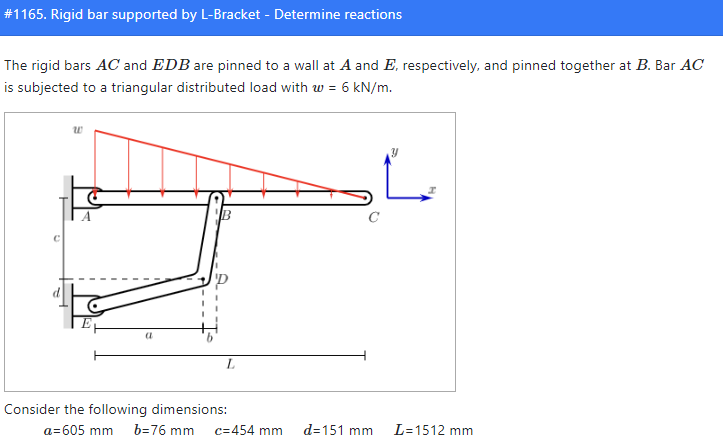

% #1165. Rigid bar supported by L-Bracket - Determine reactions

% The direction of Fb is r_EB

a = 605.0; % mm
b = 76.0; % mm
c = 454.0; % mm
d = 151.0; % mm
L = 1512.0; % mm
w = 6.0; % kN/m

fw = L*w/2

fw = 4536

MwA = fw*L/3

MwA = 2286144

syms fax fay fex fey
eqn1 = fey/fex == (c+d)/(a+b)

$$eqn1 = \frac{\mathrm{fey}}{\mathrm{fex}}=\frac{605}{681}$$

eqn2 = [fax,fay] + [fex,fey] + [0,-fw] ==0

$$eqn2 = \left(\begin{array}{cc} \mathrm{fax}+\mathrm{fex}=0 & \mathrm{fay}+\mathrm{fey}-4536=0 \end{array}\right)$$

eqn3 = fey*(a+b) == MwA;
[fax, fay, fex, fey] = vpasolve(eqn1,eqn2,eqn3,[fax, fay, fex, fey])

$$fax = -3778.7504132231404958677685950413$$

$$fay = 1178.9603524229074889867841409692$$

$$fex = 3778.7504132231404958677685950413$$

$$fey = 3357.0396475770925110132158590308$$

norm([fex,fey])

$$ans = 5054.5692082351176902787951125186$$

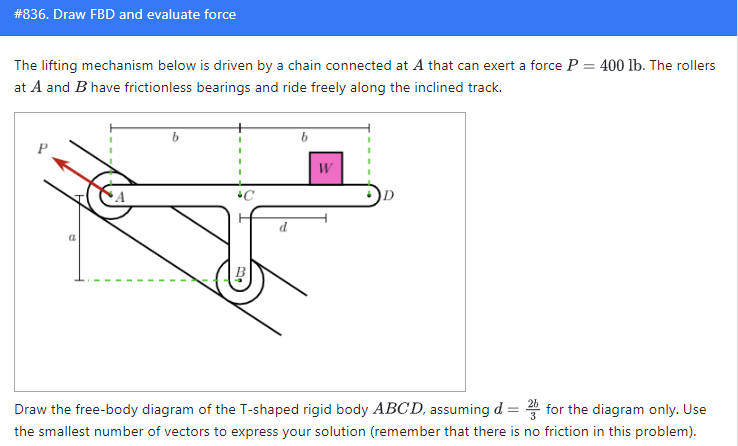

% #836. Draw FBD and evaluate force

a = 10.0; % in
b = 18.0; % in
d = 12.0; % in
P = 372.0; % lb

% theta is angle ABC
theta = atand(b/a)

theta = 60.9454

% W's projection on P 
syms w;
eqn1 = P == w*cosd(theta);
w = vpasolve(eqn1,w)

$$w = 765.9948824894328234953242881363$$


syms fb;
eqn1 = fb*sqrt(a^2+b^2) == w*(b+d)

$$eqn1 = 2\,\sqrt{106}\,\mathrm{fb}=22979.846474682984704859728644089$$

fb = vpasolve(eqn1,fb)

$$fb = 1116.0$$

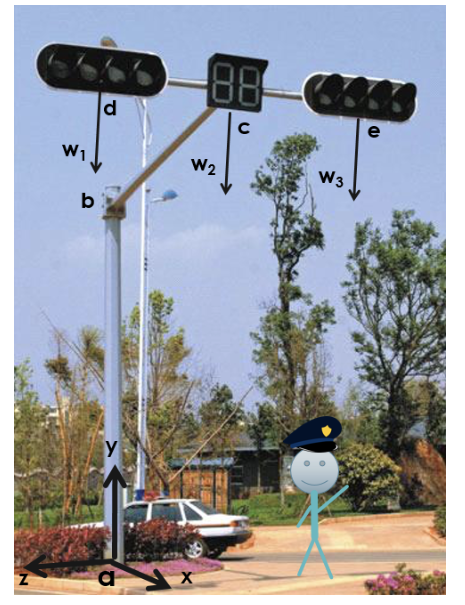

% #126. 3D Equilibrium - traffic lights

x_a = 0;
y_a = 0;
z_a = 0;
x_b = 0;
y_b = 10.45 ;
z_b = 0 ;
x_c = 3.35 ;
y_c = 10.45;
z_c = 0;
x_d = 3.35 ;
y_d = 10.45;
z_d = 3;
x_e = 3.35 ;
y_e = 10.45 ;
z_e = -2.1;
m1= 2.4;
m2= 4.5;
m3= 1.1;

a = [x_a,y_a,z_a];
b = [x_b,y_b,z_b];
c = [x_c,y_c,z_c];
d = [x_d,y_d,z_d];
e = [x_e,y_e,z_e];

mm1 = [0,-m1,0] * 9.81;
mm2 = [0,-m2,0] * 9.81;
mm3 = [0,-m3,0] * 9.81;

rf = -(mm1+mm2+mm3);
rm = cross(d,mm1) + cross(c,mm2) + cross(e,mm3);
rm = -rm

rm =   -47.9709         0  262.9080


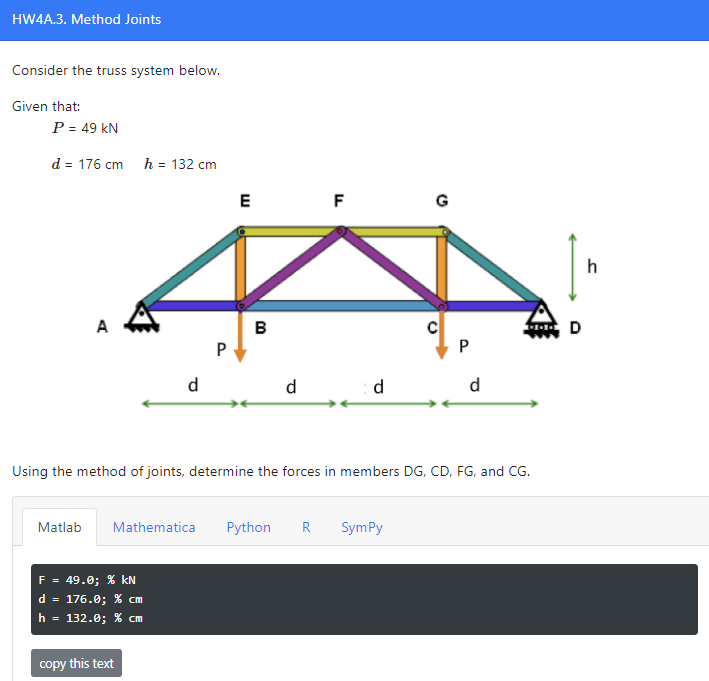

% HW4A.3. Method Joints

F = 49.0; % kN
d = 176.0; % cm
h = 132.0; % cm

syms fay fdy;
eqn1 = fay + fdy == 2*F;
eqn2 = fay*4*d == F*3*d + F*d;
[fay,fdy] = vpasolve(eqn1,eqn2,[fay,fdy]);
theta = atand(h/d);
dg = -abs(fdy/sind(theta))

$$dg = -81.666666666666666666666666666667$$

cd = abs(dg*cosd(theta))

$$cd = 65.333333333333333333333333333333$$

fg = -abs(dg*cosd(theta))

$$fg = -65.333333333333333333333333333333$$

cg = abs(dg*sind(theta))

$$cg = 49.0$$

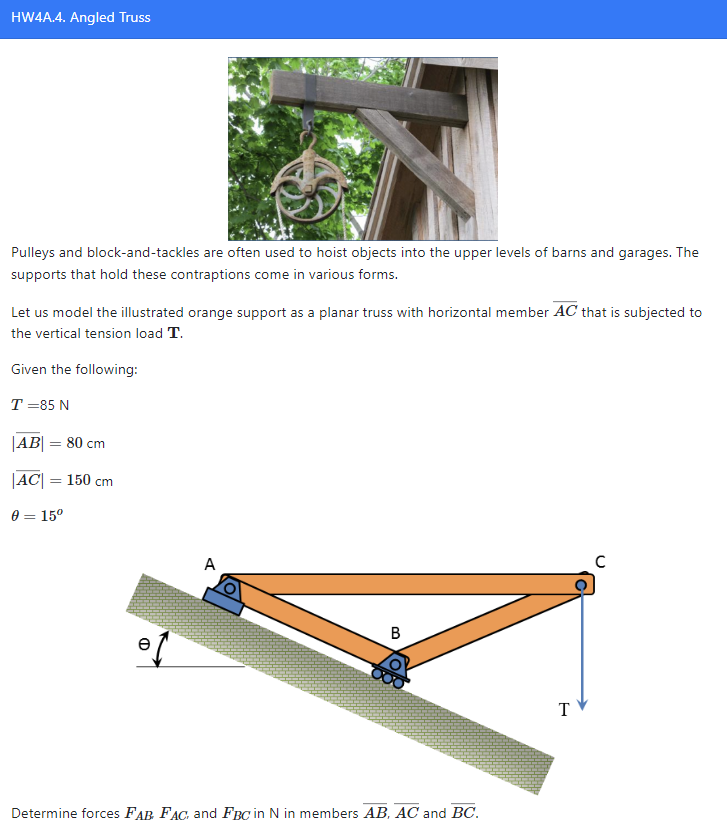

% HW4A.4. Angled Truss

T = 85.0; % N
AB = 80.0; % cm
AC = 150.0; % cm
theta = 15.0; % degrees
% View ramp as the x-axis
syms fax fay fby; 
ty = T*cosd(theta);
tx = T*sind(theta);
eqn1 = fax + tx ==0;
eqn2 = fay + fby - ty ==0;
eqn3 = T*AC - fby*AB ==0;
[fax,fay,fby] = vpasolve(eqn1,eqn2,eqn3,[fax,fay,fby]);
syms fac fab;

eqn1 = fac*cosd(theta)+fax+fab==0;
eqn2 = fac*sind(theta) + fay==0;
[fac,fab] = vpasolve(eqn1,eqn2,[fac,fab])

$$fac = 298.55339561592647787160331798808$$

$$fab = -266.38081651800662610245258596938$$

fbc = - (fac^2+T^2)^0.5

$$fbc = -310.41767029890535446635512819207$$

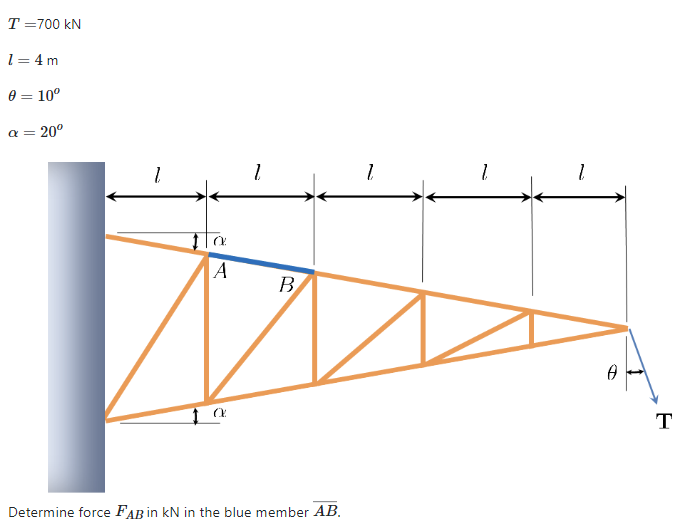

% HW4A.5. Angled load truss problem
% All member is zero-force member

t=700;
l=4;
theta = 10;
alpha = 20;
syms ab bc;
fab = ab*[cosd(alpha),-sind(alpha),0];
fbc = bc*[cosd(alpha),sind(alpha),0];
ft = t*[sind(theta),-cosd(theta),0];
eqn1 = fab + fbc + ft ==[0,0,0];
[ab,bc] = vpasolve(eqn1,[ab,bc])

$$ab = -1072.4622203665693028458660105441$$

$$bc = 943.10744873370256575818703941603$$

ab = abs(ab)

$$ab = 1072.4622203665693028458660105441$$

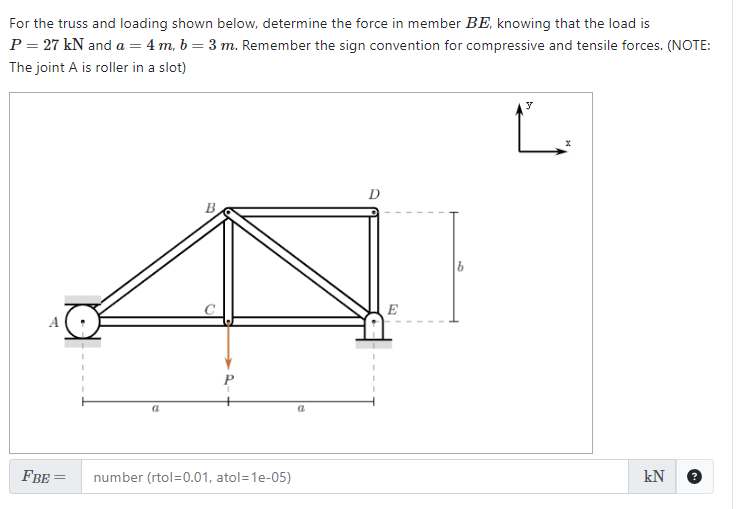

% HW4A.6. Force in truss

% For P in vertical direction 
p = 25;
a = 4;
b = 3;
% Remember to change the direction of fay fey
fay = p/2;
fey = p/2;
% BAC
theta = atand(b/a);

syms fab fac ;
eqn1 = fab*cosd(theta)+fac ==0;
eqn2 = fab*sind(theta)+fay ==0;
[fab,fac] = vpasolve(eqn1,eqn2,[fab,fac]);
syms fbe;
% Remember to change the direction of P
eqn1 = fbe*sind(theta)+fab*sind(theta) == -p;
[fbe] = vpasolve(eqn1,[fbe])

$$fbe = -20.833333333333333333333333333333$$


% For P in horizontial direction 
% Assume P is positive x direction
p = 27;
a = 4;
b = 3;
% BAC
theta = atand(b/a);
syms fay fey;
fex = -p;
eqn1 = fay*2*a + p*b ==0;
eqn2 = fay + fey == 0;
[fay,fey] = vpasolve(eqn1,eqn2,[fay,fey])

$$fay = -10.125$$

$$fey = 10.125$$


fab = -fay/sind(theta);
fbe = -fab

$$fbe = -16.875$$

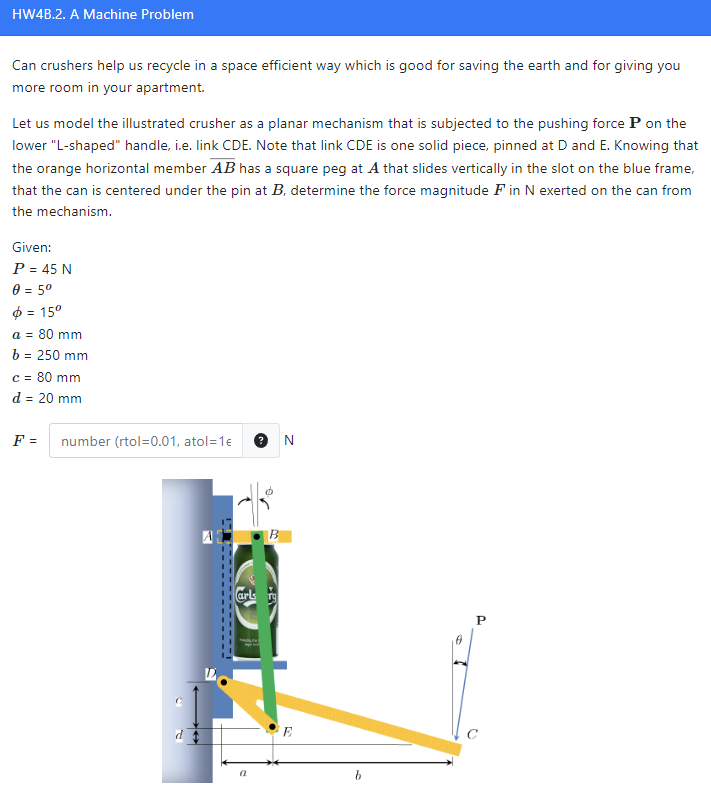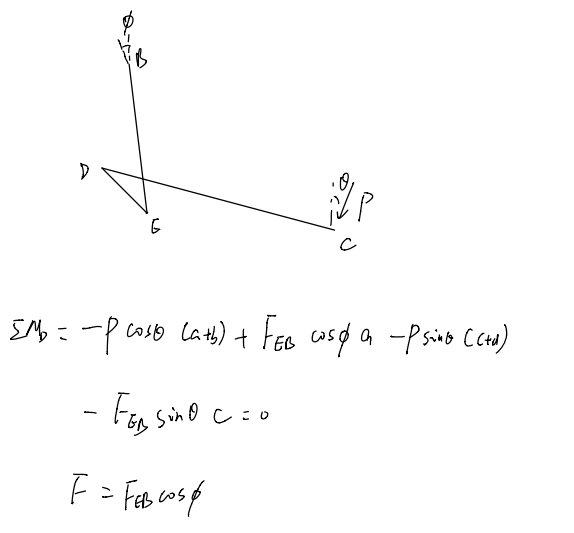

% HW4B.2. A Machine Problem

p=45;
t1=5;
t2=15;
a = 80;
b = 250;
c = 80;
d = 20;

syms feb;
eqn = -p*cosd(t1)*(a+b) + feb*cosd(t2)*a-p*sind(t1)*(c+d)-feb*sind(t2)*c ==0;

[feb] = vpasolve(eqn,feb);
f = feb*cosd(t2);
f

$$f = 259.30051493724515156574891730557$$

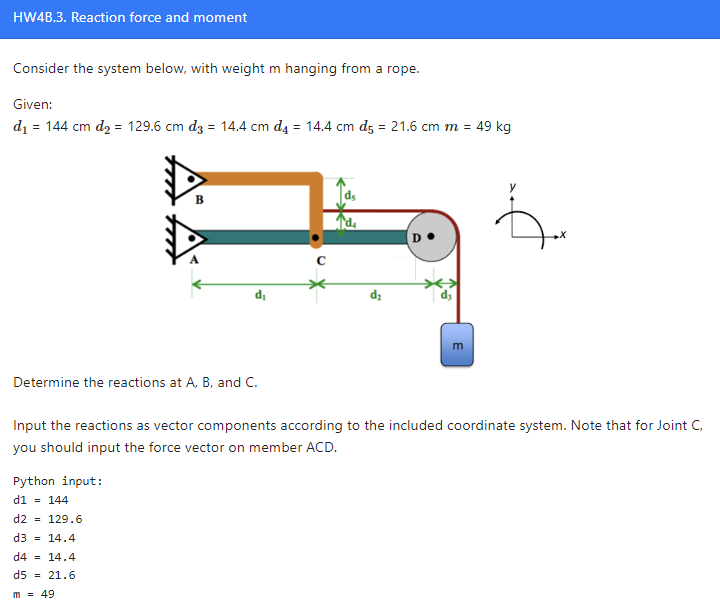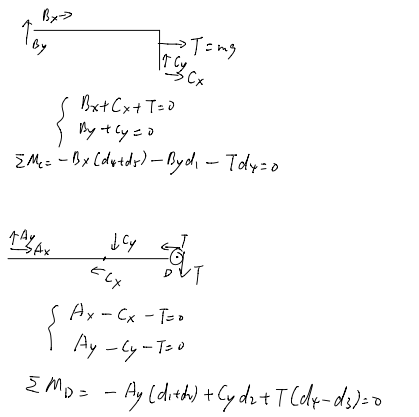

% HW4B.3. Reaction force and moment
d1 = 144.0; % cm
d2 = 129.6; % cm
d3 = 14.4; % cm
d4 = 14.4; % cm
d5 = 21.6; % cm
m = 49.0; % kg
m = m*9.81;

syms fax fay fbx fby fcx fcy;

ffc = [fcx,fcy,0];
ffa = [fax,fay,0];
ffb = [fbx,fby,0];


m1 = [m,0,0];

m0 = [0,-m,0];
m2 = [-m,0,0];

eqn1 = ffb + ffc + m1 == [0,0,0];

rcb = [-d1,d4+d5,0];
rcm = [0,d4,0];
eqn2 = -fbx*(d4+d5) - fby * d1 - m*d4 == 0;
eqn3 = ffa - ffc + m2 + m0 == [0,0,0];

rda = [-d1-d2,0,0];
rdc = [-d2,0,0];
rdm2 = [0,d4,0];
rdm0 = [d3,0,0];
eqn4 = -fay*(d1+d2) + fcy * d2 + m*(d4-d3) ==0;

[fax ,fay ,fbx ,fby ,fcx,fcy] = vpasolve([eqn1,eqn2,eqn3,eqn4],[fax ,fay ,fbx ,fby ,fcx,fcy])

$$fax = 3845.5199999999999915113827834527$$

$$fay = -432.621$$

$$fbx = -3845.5199999999999915113827834527$$

$$fby = 913.311$$

$$fcx = 3364.8299999999999915113827834527$$

$$fcy = -913.311$$

fcx = -fcx

$$fcx = -3364.8299999999999915113827834527$$

fcy = -fcy

$$fcy = 913.311$$

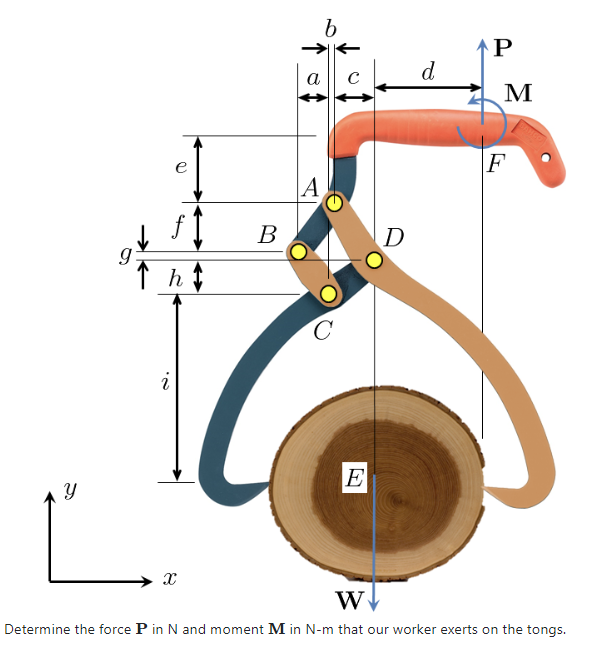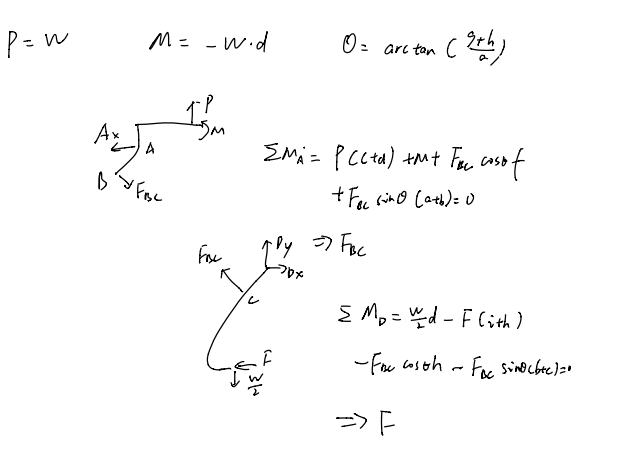

% HW4B.4. Clamping Mechanism Problem
a = 35.0; % mm
b = 10.0; % mm
c = 45.0; % mm
d = 190.0; % mm
e = 80.0; % mm
f = 45.0; % mg
g = 10.0; % mm
h = 35.0; % mm
i = 285.0; % mm

w = 220;
p = w

p = 220

M = -w*d

M = -41800

M/1000

ans = -41.8000

theta = atand((g+h)/a);
syms F Fbc;
eqn1 = p*(c+d) + M +  Fbc * cosd(theta)*f +Fbc*sind(theta)*(a+b)==0;

eqn2 = w/2*d - F*(i+h)-Fbc*cosd(theta)*h - Fbc*sind(theta)*(b+c)==0;

[F,Fbc] = vpasolve(eqn1,eqn2,[F,Fbc])

$$F = 97.109375$$

$$Fbc = -156.77412095113147213120674101543$$

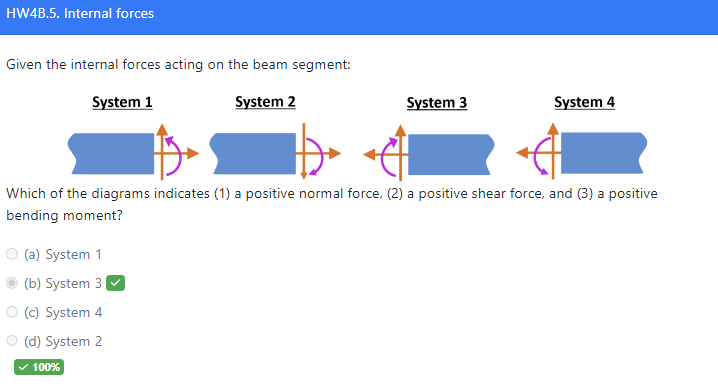

% Internal forces directions

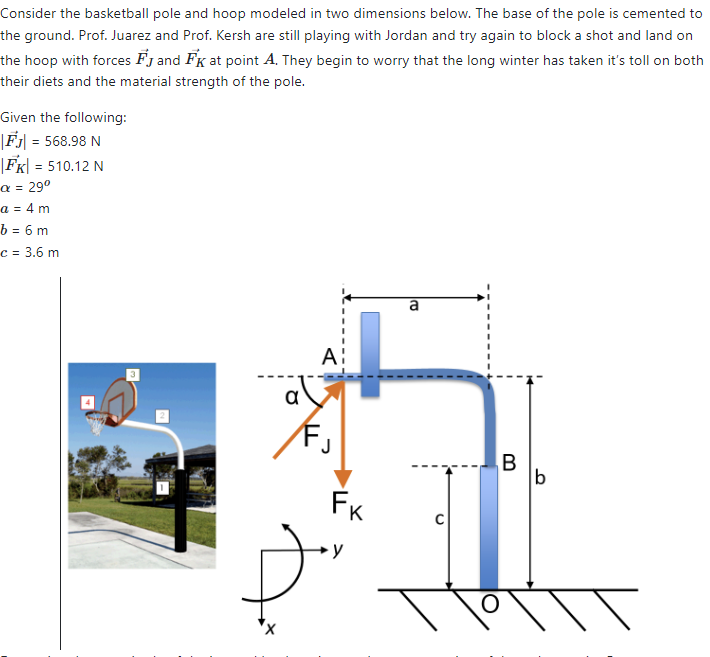

% HW4B.6. Internal forces
% Determine the magnitude
Fj = 569.0; % N
Fk = 510.1; % N
a = 4.0; % m
b = 6.0; % m
c = 3.6; % m
alpha = 29.0; % deg


fk = [Fk,0,0];
fj = [-Fj*sind(alpha),Fj*cosd(alpha),0];

r = [-b,-a,0];
rs = [-c,0,0];
force = -(fk+fj);
sf = ([0,force(2),0]);
fn = ([force(1),0,0]);
M = cross(r,force);

m1 = abs(cross(rs,sf));
M = (M-m1);

fn = abs(fn(1))

fn = 234.2433

sf = abs(sf(2))

sf = 497.6586

M= M(3)

M = 257.4074

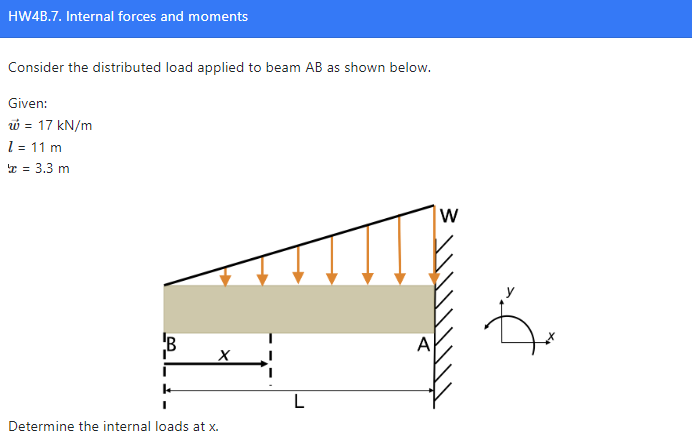

% HW4B.7. Internal forces and moments

%% 4B.7
w = 17.0; % kN/m
l = 11.0; % m
x = 3.3; % m

syms a;

fun = w/l*(a-(l-x)) + w;

fn = 0

fn = 0

fs = vpa(-int(fun,-x,0))

$$fs = -8.415$$

mtotal = vpa(int(fun*a,-x,0))

$$mtotal = -9.2565$$

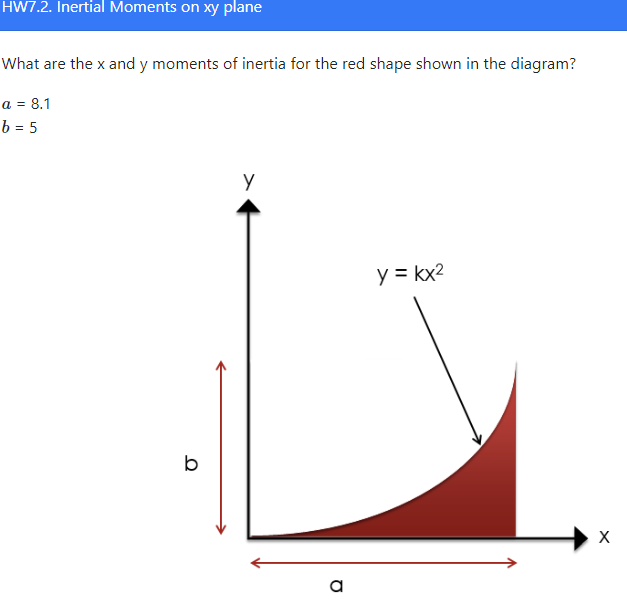

%% HW7.2  Inertial Moments on xy plane
%% Y = KX^2
%% Moment 计算需要记住 Ix = y^2*dA
a = 8.1; % 
b = 5.0; % 
k=b/a^2;

syms x y;
I1=int(y^2*(a-sqrt(y/k)),y,0,b);
I2=int(x^2*k*x^2,x,0,a);
vpa([I1,I2])

$$ans = \left(\begin{array}{cc} 48.214285714285714285714285714286 & 531.441 \end{array}\right)$$

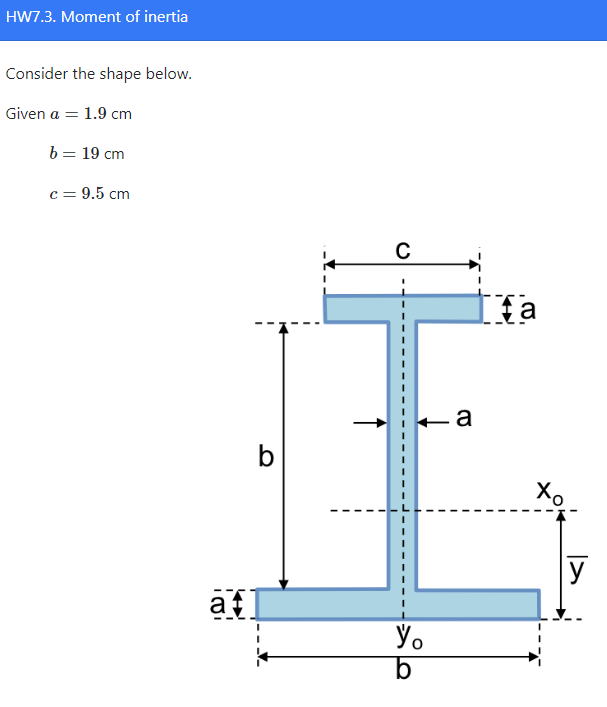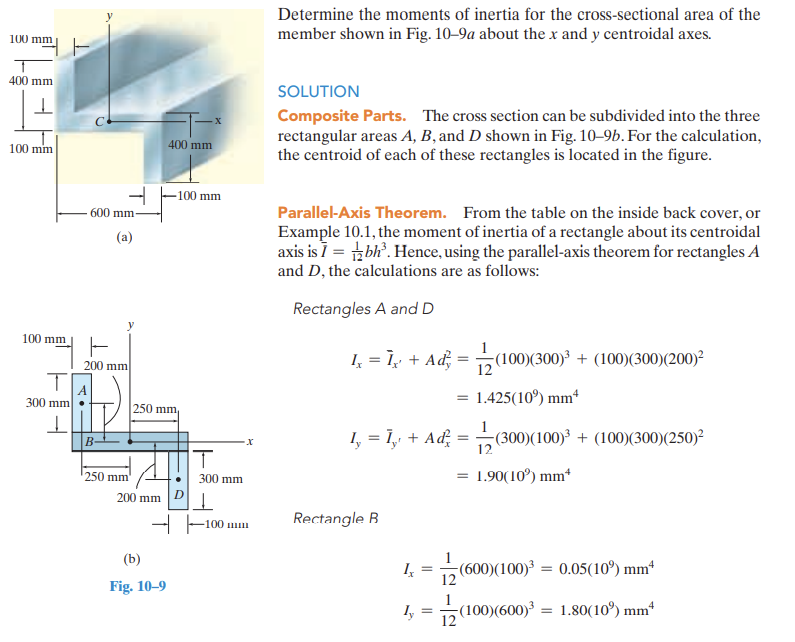

%% HW7.3 Moment of inertia

a = 1.9; % cm
b = 19.0; % cm
c = 9.5; % cm
%% 先算出yave 及该物体的重心 然后积分 也可以用定理 公式中 dx是重心之间的距离
%% 矩形: Ix = bh^3/12   计算Ix b就是和x轴平行的边！！！
%% 圆:   Ix = pi*r^4/4   
A=a*b+a*b+a*c;
yave=(a*b*0.5*a+b*a*(b/2+a)+a*c*(a+b+1/2*a))/A;
syms	x	y;
% Ix=vpa(int(y^2*b,y,-yave,-yave+a)+int(y^2*a,y,-yave+a,-yave+a+b)+int(y^2*c,y,-yave+a+b,-yave+a+b+a))
I1 = b*a^3/12 + a*b*(yave-a/2)^2;
I2 = c*a^3/12 + a*c*(yave-a-b-a/2)^2;
I3 = a*b^3/12 + a*b*(yave-a-b/2)^2;
Ixx = vpa(I1+I2+I3)

$$Ixx = 6621.3928083333339600358158349991$$


I4 = a*b^3/12;
I5 = a*c^3/12;
I6 = b*a^3/12;
Iyy = vpa(I4 + I5 + I6)

$$Iyy = 1232.6194583333331138419453054667$$

%% Iy=vpa(int(x^2*a,x,-b/2,b/2)+int(x^2*b,x,-a/2,a/2)+int(x^2*a,x,-c/2,c/2))

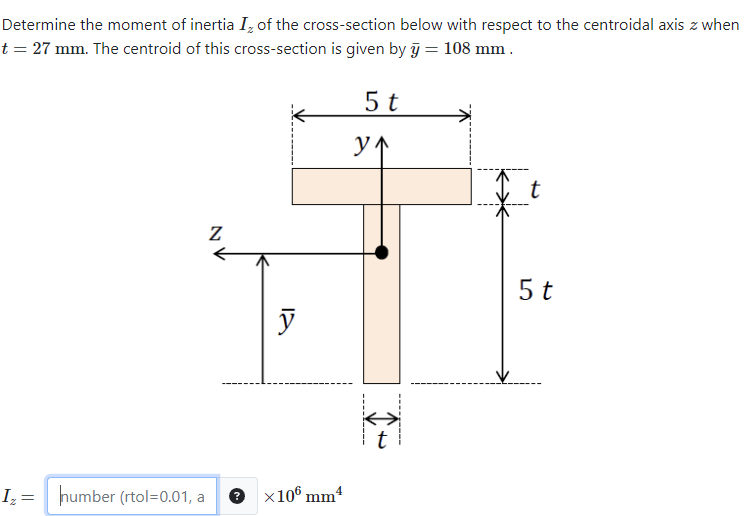

%% HW7.4. Find centroid composite cross section
t = 27;
y_a = 108;
%% 继续用定理 
I1 = t*(5*t)^3/12 + 5*t^2*abs(y_a-5/2*t)^2;
I2 = 5*t*(t)^3/12 + 5*t^2*abs(y_a-5.5*t)^2;
Iz = vpa(I1 + I2)

$$Iz = 17714700.0$$

Izz = Iz/10^6

$$Izz = 17.7147$$

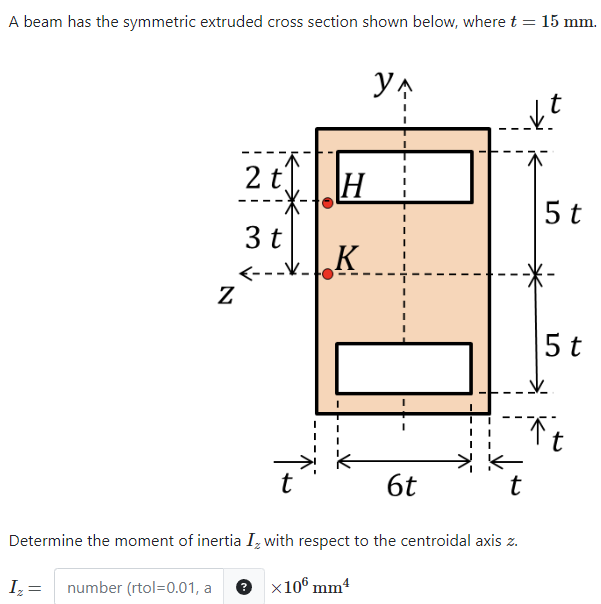

%% HW7.5. Determine the moment of inertia

t = 15;
I1 = 6*t*(2*t)^3/12+ 2*t*6*t*(4*t)^2;
I2 = 8*t*(12*t)^3/12;
Iz = vpa(I2-2*I1)

$$Iz = 38475000.0$$

Iz = Iz/10^6

$$Iz = 38.475$$

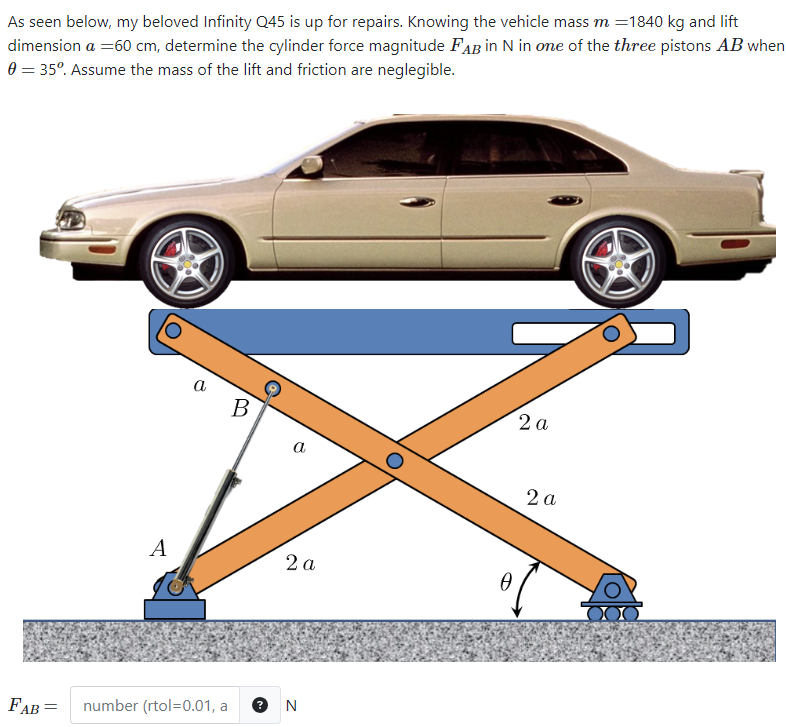

%% HW7.6. A little hard virtual work problem

a = 0.6;
m = 1840;
theta = 35;

w = m * 9.81;
syms va t;
ab = sqrt(5*va^2-4*va^2*cos(2*t))

$$ab = \sqrt{5\,{\mathrm{va}}^{2}-4\,{\mathrm{va}}^{2}\,\cos\left(2\,t\right)}$$

dab = diff(ab,t)

$$dab = \frac{4\,{\mathrm{va}}^{2}\,\sin\left(2\,t\right)}{\sqrt{5\,{\mathrm{va}}^{2}-4\,{\mathrm{va}}^{2}\,\cos\left(2\,t\right)}}$$

dab = subs(fn,[va,t],[a,theta*[pi/180]]);
dab = vpa(dab)

$$dab = 1.1833928897148154723330374631462$$

dh = 4*a*cosd(theta);
%% dab = 4*a*sind(2*theta)/sqrt(5-4*cosd(2*theta))
%% 题目里说了有三根
Fab = vpa(dh*w/dab)/3

$$Fab = 9995.6808520607452188757258501031$$

%% HW7.7. Virtual work - conceptual

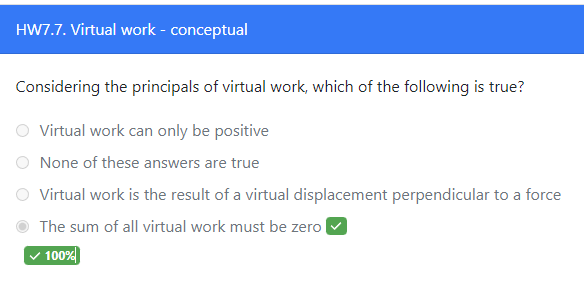

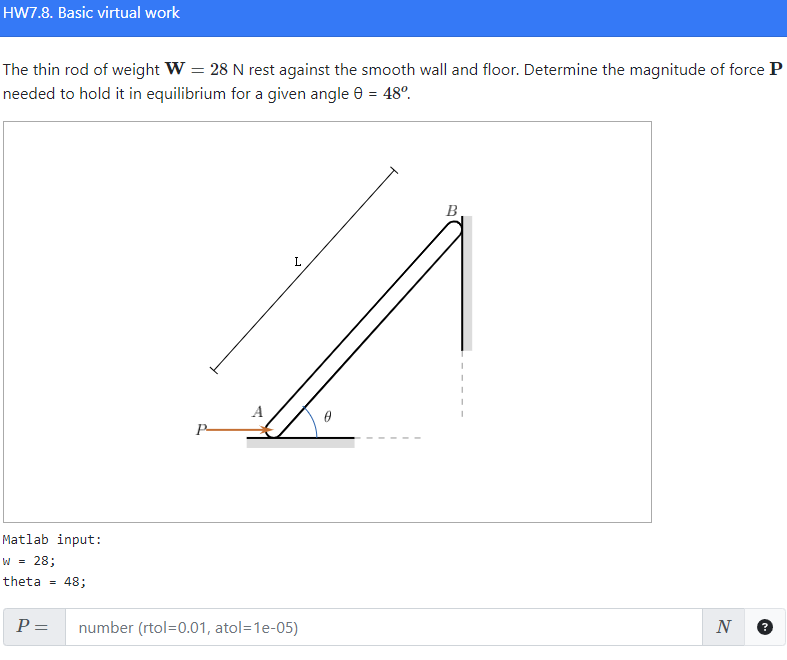

%% HW7.8. Basic virtual work

w = 28; 
theta = 48;
Fb=w*cosd(theta)/2/sind(theta);
P=Fb

P = 12.6057

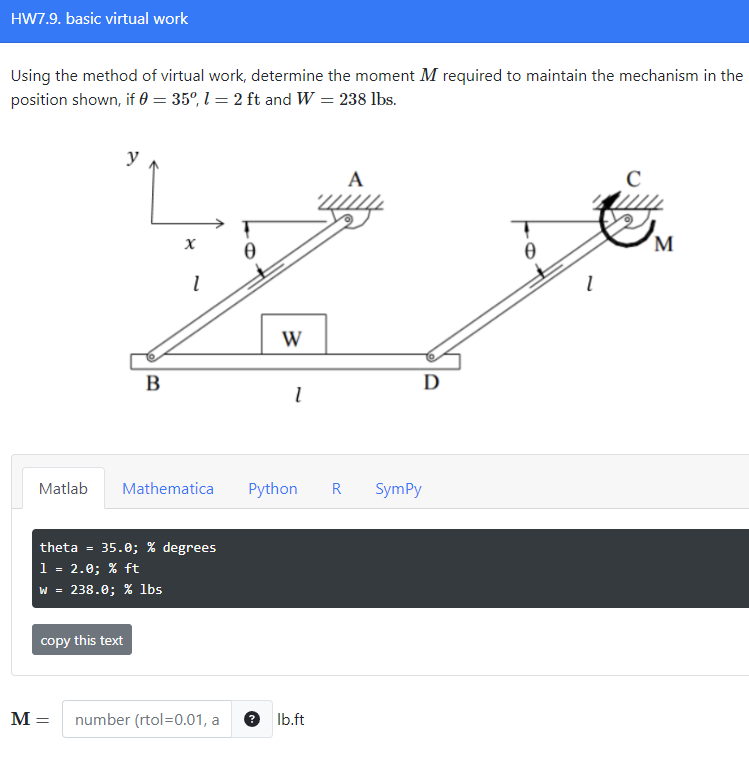

%% HW7.9. basic virtual work

theta = 35.0; % degrees
l = 2.0; % ft
w = 231.0; % lbs

M = w*l*cosd(theta)

M = 378.4482